% Cubic Trajectory Planning in MATLAB
% Given parameters
q0 = 0;      % initial position
qf = 10;     % final position
v0 = 0;      % initial velocity
vf = 0;      % final velocity
t_total = 10; % total time for the motion (seconds)

% Time vector
t = linspace(0, t_total, 1000);

% Coefficients for cubic polynomial
A = [1, 0, 0, 0;
     0, 1, 0, 0;
     1, t_total, t_total^2, t_total^3;
     0, 1, 2*t_total, 3*t_total^2];
b = [q0; v0; qf; vf];
coeffs = A\b;

a0 = coeffs(1);
a1 = coeffs(2);
a2 = coeffs(3);
a3 = coeffs(4);

% Compute position, velocity, and acceleration
q = a0 + a1*t + a2*t.^2 + a3*t.^3;
v = a1 + 2*a2*t + 3*a3*t.^2;
a = 2*a2 + 6*a3*t;

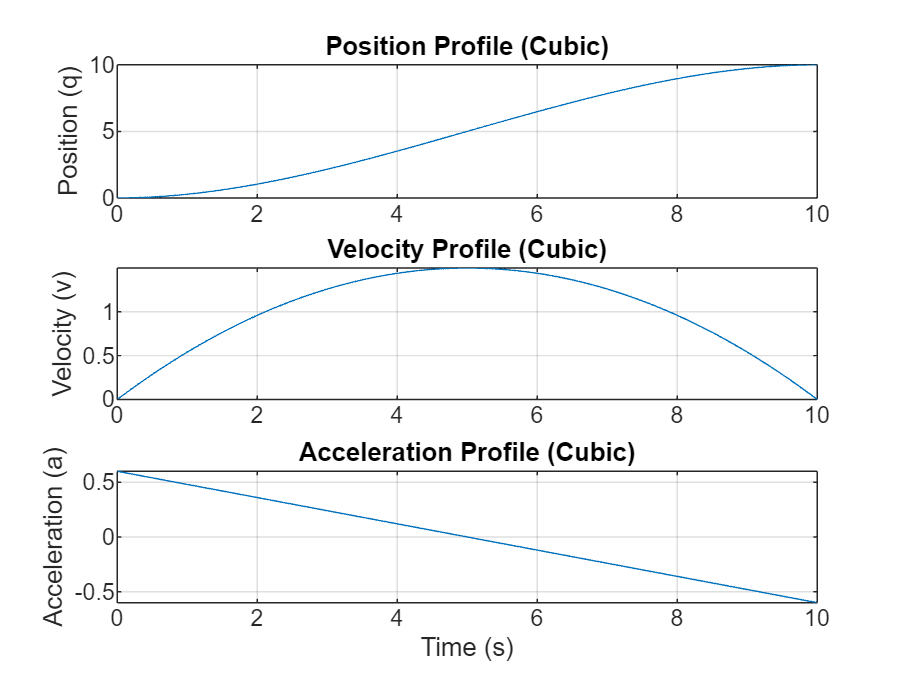

% Plot the trajectory
figure;
subplot(3,1,1);
plot(t, q);
title('Position Profile (Cubic)');
ylabel('Position (q)');
grid on;

subplot(3,1,2);
plot(t, v);
title('Velocity Profile (Cubic)');
ylabel('Velocity (v)');
grid on;

subplot(3,1,3);
plot(t, a);
title('Acceleration Profile (Cubic)');
ylabel('Acceleration (a)');
xlabel('Time (s)');
grid on;